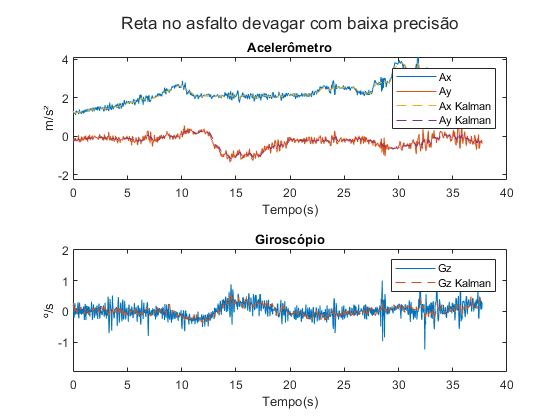

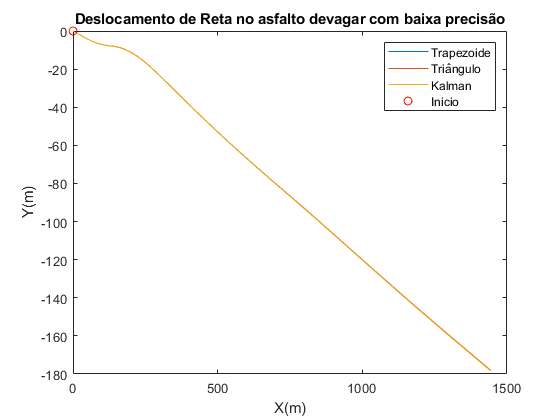

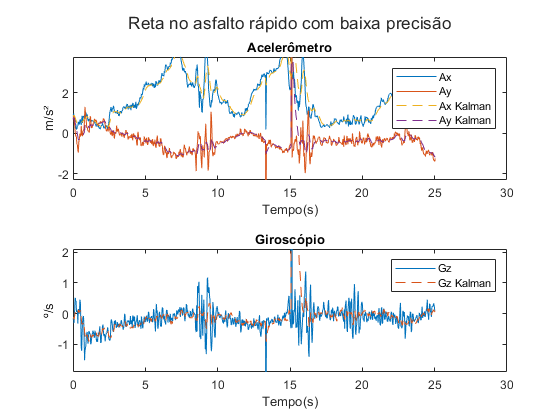

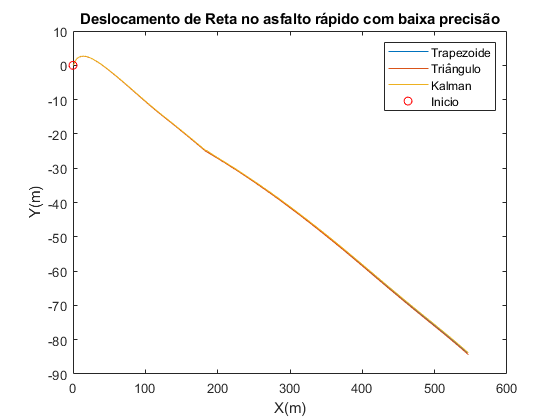

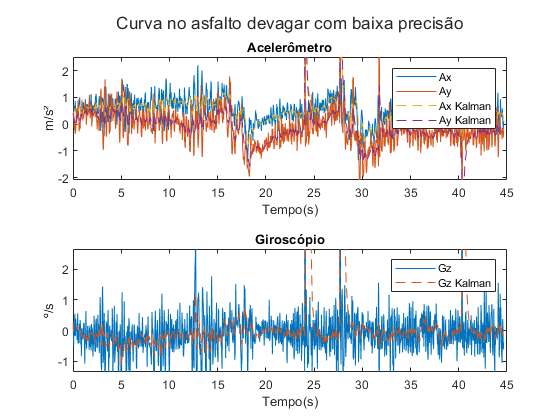

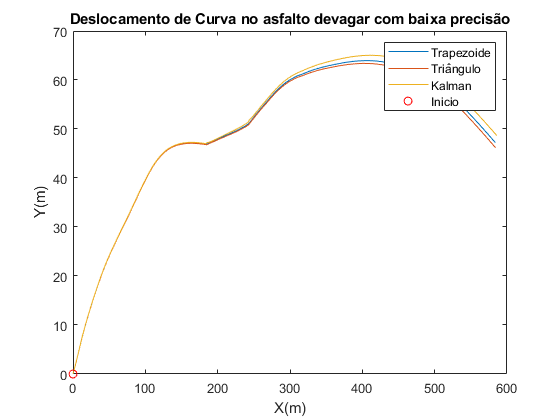

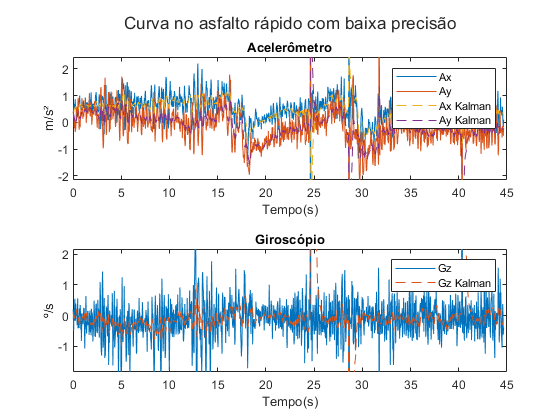

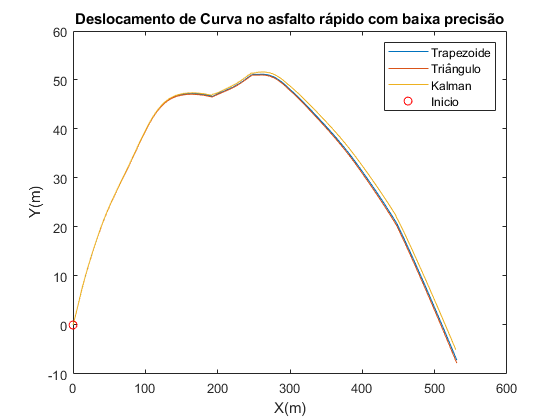

load('Leitura.mat')
%graficos
%casos unidimensionais
%nome mean 
dados = cell(length(medicoes),10);
resultados = cell(length(medicoes),13);
for i=1:length(medicoes)
    %valores reais
    Ax=medicoes(i).valores.Ax;
    Ay=medicoes(i).valores.Ay;
    Gz=medicoes(i).valores.Gz;
    Tempo=medicoes(i).valores.Ms/1000;
    %integração trapezoidal
    %interpolando para intervalo de amostragem padrao
    Tempo=medicoes(i).valores.Ms/1000;
    dT_amostragem=mean(diff(Tempo));
    Tempo_amostragem = Tempo(1):dT_amostragem:Tempo(end);
    Axm=interp1(Tempo,Ax,Tempo_amostragem);
    Aym=interp1(Tempo,Ay,Tempo_amostragem);
    Gzm=interp1(Tempo,Gz,Tempo_amostragem);
    %filtro na interpolação
    Axf=Kalman1DInt(dT_amostragem,Axm,false);
    Ayf=Kalman1DInt(dT_amostragem,Aym,false);
    Gzf=Kalman1DInt(dT_amostragem,Gzm,true);
    titulo=TituloRota(medicoes(i).R,medicoes(i).A);
    Px_kalman=Axf.Deslocamento;
    Py_kalman=Ayf.Deslocamento;
    Px_trapz=cumtrapz(Tempo,cumtrapz(Tempo,Ax));
    Py_trapz=cumtrapz(Tempo,cumtrapz(Tempo,Ay));
    Px_tri=IntTriang(Tempo,IntTriang(Tempo,Ax));
    Py_tri=IntTriang(Tempo,IntTriang(Tempo,Ay));
    figure();
    t=tiledlayout(2,1);
    ax1=nexttile;
    plot(ax1,Tempo,Ax,Tempo,Ay,Tempo_amostragem,Axf.Accel,'--',Tempo_amostragem,Ayf.Accel,'--');
    ax2=nexttile;
    plot(ax2,Tempo,Gz,Tempo_amostragem,Gzf.Gyro,'--');
    title(t,titulo);
    title(ax1,"Acelerômetro");
    title(ax2,"Giroscópio");
    xlabel(ax1,"Tempo(s)");
    ylabel(ax1,'m/s²');
    xlabel(ax2,"Tempo(s)");
    ylabel(ax2,'º/s');
    legend(ax1,["Ax","Ay","Ax Kalman","Ay Kalman"]);
    legend(ax2,["Gz","Gz Kalman"]);
    %limites
    minimo = min([mean(Axf.Accel),mean(Ayf.Accel)]) -2;
    maximo = max([mean(Axf.Accel),mean(Ayf.Accel)]) +2;
    ylim(ax1,[minimo,maximo]);
    ylim(ax2,[-2,2]+mean(Gzf.Gyro));
    %rota
    figure();
    plot(Px_trapz,Py_trapz,Px_tri,Py_tri,Px_kalman,Py_kalman,0,0,'ro');
    title("Deslocamento de "+ titulo);
    legend(["Trapezoide","Triângulo","Kalman","Inicio"]);
    xlabel('X(m)');
    ylabel('Y(m)');
    
    varAx=var(Ax);
    varAy=var(Ay);
    varGz=var(Gz);
    varAxk=var(Axf.Accel);
    varAyk=var(Ayf.Accel);
    varGzk=var(Gzf.Gyro);
    coefAx=100-varAxk*100/varAx;
    coefAy=100-varAyk*100/varAy;
    coefGz=100-varGzk*100/varGz;
    
    dados(i,:)= {titulo,varAx,coefAx,varAy,coefAy,varGz,coefGz,...
        distLinha(Px_trapz,Py_trapz),distLinha(Px_tri,Py_tri),...
        distLinha(Px_kalman,Py_kalman)};
    resultados(i,:)={i,Tempo,Ax,Ay,Gz,Tempo_amostragem,Axf,Ayf,Gzf,Px_tri,Py_tri,Px_trapz,Py_trapz};
    
end

tabela=cell2table(dados,"VariableNames",["Rota","Variância Ax","Redução da Var. Ax com Kalman(%)",...
    "Variância Ay","Redução da Var. Ay com Kalman(%)",...
    "Variância Gz","Redução da Var. Gz com Kalman(%)",...
    "Distância por Trapz.(m)","Distância por Triâng.(m)","Distância por Kalman(m)"]);
tabela

tabela = 16×10 table
                        Rota                         Variância Ax    Redução da Var. Ax com Kalman(%)    Variância Ay    Redução da Var. Ay com Kalman(%)    Variância Gz    Redução da Var. Gz com Kalman(%)    Distância por Trapz.(m)    Distância por Triâng.(m)    Distância por Kalman(m)
    _____________________________________________    ____________    ________________________________    ____________    ________________________________    ____________    ________________________________    _______________________    ________________________    _______________________

    "Reta no asfalto devagar com baixa precisão"       0.38104

tab_resultados=cell2table(resultados);
tab_resultados.Properties.VariableNames=["Caso","Tempo","Ax","Ay","Gz",...
    "Tempo amostrado","Ax Kalman","Ay Kalman","Gz Kalman","Px Triângulo","Py Triângulo","Px Trapez.","Py Trapez."];
tab_resultados

tab_resultados = 16×13 table
    Caso         Tempo               Ax                 Ay                 Gz                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                         

function titulo=TituloRota(R,A)
    titulo= "";
    switch R
        case 1
            titulo = titulo + "Reta no asfalto devagar ";
        case 2
            titulo = titulo + "Reta no asfalto rápido ";
        case 3
            titulo = titulo + "Curva no asfalto devagar ";
        case 4
            titulo = titulo + "Curva no asfalto rápido ";
        case 5
            titulo = titulo + "Reta no chão devagar ";
        case 6
            titulo = titulo + "Reta no chão rápido ";
        case 7
            titulo = titulo + "Curva no chão devagar ";
        case 8
            titulo = titulo + "Curva no chão rápido ";
    end
    switch A
        case 1
            titulo =titulo + "com baixa precisão";
        case 4
            titulo =titulo + "com alta precisão";
    end
end

function dados=Kalman1DInt(dT,f,isAngle,qm,rm)
%kalman 1d com integração
    if nargin == 3
        rm=1;
        qm=1;
    elseif nargin ==4
        rm=1;
    end
    %incializa
    tamanho=length(f);
    if isAngle
        %xk=[gz; oz]
        Xk=zeros(2,tamanho);
        Xk_prev=zeros(2,1);
        X_pred=Xk_prev;
        H=[1,0];
        A=[1,0;dT,1];
        Pk_prev=eye(2);
        I=eye(2);
        vvar=0.05;
        wvar=[vvar;vvar*dT];
        n=2;
        
    else
        %xk=[a;v;p]
        Xk=zeros(3,tamanho);
        Xk_prev=zeros(3,1);
        X_pred =Xk_prev;
        H=[1,0,0];
        A=[1,0,0;dT,1,0;dT^2 /2, dT,1];
        Pk_prev=eye(3);
        I=eye(3);
        vvar=400*9.81*1e-6 *sqrt(dT);
        wvar=[vvar;vvar*dT;vvar*dT^2 /2];
        n=3;
    end
    Q=wvar*wvar.' * dT;
    R=vvar^2;
    for i=1:tamanho
        z=f(i);
        v=randn(1) * vvar;
        w=randn(n,1) .* wvar;
        %predicao
        X_pred=A*Xk_prev+w;
        P_pred=A*Pk_prev*(A.')+Q;
        %atualização
        Kk=P_pred*(H.')/(H*P_pred*(H.')+R);
        Xk(:,i)=X_pred+Kk*(z-H*X_pred - v);
        Pk=(I-Kk*H)*P_pred*((I-Kk*H).')+Kk*R*(Kk.');
        if isAngle %impede overflow de grau
            Xk(:,i)=rem(Xk(:,i),360);
            Pk=rem(Pk,360);
        end
        Xk_prev=Xk(:,i);
        %anteriores
        Pk_prev=Pk;
    end
    if isAngle
        dados=array2table(Xk.','VariableNames',{'Gyro','Angulo'});
    else
        dados=array2table(Xk.','VariableNames',{'Accel','Velocidade','Deslocamento'});
    end
end

function valor=porcentagemDif(a1,a2)
    valor=(1-a2/a1)*100;
end

function comp=distLinha(x,y)
    d=diff([x(:) y(:)]);
    comp=sum(sqrt(sum(d.^2,2)));
end